# Practical4

## Question Form

## Part 1

A reaction is being carried out in a CSTR of volume 10 m3. The feed solution contains a reagent at concentration of 5 kmol/m3 and is supplied at a rate of 10-2 m3/s. The reagent decomposes irreversibly according to a first-order reaction, liberating 2e7 J/kg. The velocity constant of the reaction is given by:  


$$k={10}^{13} \;\exp \left(-\frac{12000}{T}\right)$$


The density of the solution is 850 kg/m3 and can be taken as being independent of temperature or  extent of reaction. The specific heat of the solution is similarly constant and equals to 2200 J kg-1. **Calculate the reaction temperature and extent of reaction** if the feed solution is provided at: [290K; 300K;  310K]. 

### Theory

The generated heat (Q) versus Temperature plot has an exponentional behavior, and expressed as follows:


$$\begin{array}{l}
Q_g =-\frac{{\textrm{vC}}_0 \Delta H}{1+k\;\frac{v}{V}}\\
Q=v\rho \;C\left(T-T_0 \right)
\end{array}$$


Which $T$ indicates reactor temperature and $T_0$ indicates feed temperature. 

In the stable condition, Q-T plot means that two Qs are balancing each other, and have an intersection point! As an engineer, the main goal is to find the intersection point. 

### Input Data and Calculations

close all, clear, clc
global V c0 c_0 Q rho cp delH_rxn T_feed nu UA k0 Tcool
V = 10; % m^3
c0 = 5; % kmol/m^3
Q = 1e-2; % m^3/s
k0 = 10^13; % 1/s
rho = 850; % kg/m^3
cp = 2200; % kJ/kg-K
delH_rxn = 2*10^7; % kJ/kmol
T_feed = 310; % K - It's nat as same as reactor temp
UA = 9000; % kJ/K-s
Tcool = 310; % K
fun = @heat_balance1; % Define the heat balance function
nu = [-1 1];        % Stoichiometric matrix
T0 = 500; % Initial value of T (K)
% Initial value of c
c_0_in = [c0 0]; % kmol/m^3
% Initial Concentration at inlet for feed 
c_0 = c_0_in;
y = [T0 c_0_in];
options = optimoptions('fsolve','Display','iter');
out = fsolve(fun,y,options);


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          4         1.81739e+13                        1.18e+11              1
     1          8         1.79384e+13              1         1.17e+11              1
     2         12         1.73565e+13            2.5         1.15e+11            2.5
     3         16         1.59438e+13           6.25         1.11e+11           6.25
     4         20         1.26745e+13         15.625         9.86e+10           15.6
     5         24         6.14135e+12        39.0625         6.86e+10           39.1
     6         28         1.04288e+10        95.3012         1.89e+09           97.7
     7         32         1.84937e+08        20.0808         1.81e+08            238
     8         36              327912        17.5728         6.96e+06            238
     9         40             1.54404        1.69247          1.

### Post Processing

%conversion of reactant A is : 
% please note there are two "c0" terms :  c_0 and c0, the first one is a vector
X = (c0 - out(2))/c0 *100;
T_final = out(1); 
disp("reactor temperature : "+ T_final)

reactor temperature : 339.4766


disp("conversion : "+ X)

conversion : 81.6503


## Heat Characteristics Curves

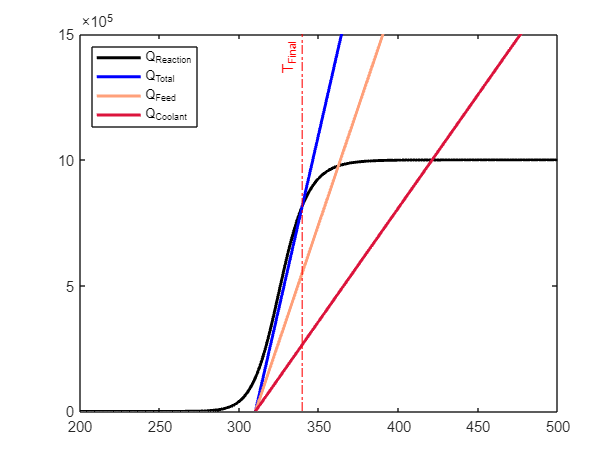

T_reactor = linspace(0,500,500);
Q_rxn = ((Q*c0* delH_rxn)./((Q./((k0) * exp(-12000./T_reactor)*V)) + 1));
Q_feed = Q*rho*cp*(T_reactor-T_feed);
Q_cool = UA*(T_reactor - Tcool);
Q_tot = Q_feed + Q_cool;

figure(1)
plot(T_reactor, Q_rxn, 'Color','k','LineWidth',2);
hold on
plot(T_reactor, Q_tot, 'Color','b','LineWidth',2);
plot(T_reactor, Q_feed, 'Color','#FFA07A','LineWidth',2);
plot(T_reactor, Q_cool, 'Color','#DC143C','LineWidth',2);
xlim([200 500])
ylim([0 15*10^5])
xline(T_final, '-.r', 'T_{Final}', 'LineWidth',1, 'LabelHorizontalAlignment','left')
legend('Q_{Reaction}', 'Q_{Total}', 'Q_{Feed}','Q_{Coolant}', 'Location', 'northwest', 'Orientation','vertical')

We can Shift the straight line to right by raising feed temperature!

Additional Cooling is a technique to 

## Part 2

With the reactor of the previous part it is found that the occurrence of a side reaction requires that  the reactor temperature must remain below 340K. show that if a cooling coil is fitted in the CSTR it will  be possible to obtain 80% conversion with no problems ignition at start-up. If the coolant temperature,  Tcool, is 310K, the feed solution is provided at 310K, and the value of UA equal to 9000 W K-1. 

## Part 3

The temperature of the solution fed to the reactor of the previous part drops to 300K. Show that  the reactor will continue to produce 80% conversion if the coolant temperature, Tcool, is raised to 331K.  Comment on the role now played by the cooling coil.

## Part 4

Show that in the reactor of the Part 1 it will no longer be possible to obtain a high level of conversion  if the feed rate is doubled, its temperature being 300K. if, at this feed rate of 210-2 m3 s-1, the feed temperature is raised to 310K, show that a conversion of over 90% is obtainable, without the need for  any heating at start-up. 

## Part 5

Following damage to the lagging, heat losses during the winter from the reactor in Part 1 are found  to be given by an expression of the form:


$$\textrm{heat}\;\textrm{loss}=5000\left(T-280\right)\;\;\left\lbrack \frac{J}{s}\right\rbrack$$


Show that the reaction will be substantially quenched if the feed rate is dropped to 2*10-3 m3/s, its  temperature remaining at 310K. What conversion will now be obtained? 

## Jalal's Notes

To get the temperature, concentration, and conversion in a CSTR reactor, we need to write a mass and energy balance on the system. We know that a CSTR has continues input and output of material, and it is fully homogenous. So, in this case the control volume is the whole volume of the reactor. According to the equation that we wrote, we need volumetric flow rate, initial concentration of species, delta_ HR, reaction rate, UA, and the coolant temperature. All of these data are given to us by the problem. So, now we could implement them in Matlab and get the conversion and temperature of the reactor. In this reactor, when we increase the feed temperature, this will result in the increase of reactor temperature and consequently increase the conversion. In this case, the 300k temperature, is an unstable point, because a small increase in this temperature will enhance the conversion a lot, and wise versa. This is due to the fact that this point is in the middle of the intersection of Q_ gen with Q_ ext (stability criteria: Q_ gen< Q_ ext). Now, if we want to keep the reactor temperature under 340k and have a conversion higher than 80%, we need to control the temperature of the reactor with a cooling jacket which has the temperature of 310k and UA of 9000 w/k. in this way we could work in higher feed temperature, without reaching to temperature higher than 340k in the reactor. In this case, if we reduce the feed temperature, it is obvious that the conversion will drop. To make up for this decrease in feed temperature, we could increase the coolant temperature to 331k resulting in increase of conversion. This is due to the fact that, this increases the Q_ external and consequently the reactor temperature increase. Changing the inlet flow rate, could have an effect on the conversion and reactor temperature. If we increase the flow rate, more reactant will go to the system, and if the feed temperature would be enough high to initiate the reaction, the temperature increase and result in an increase of conversion. But, if the temperature is not high enough this increase in flow rate transports more heat with itself from the reactor to the outlet, and result in the failure of reactor.